# Characteristic scales for brine percolation in Europa's ice shell

First all the primary parameters

H = 30e3;        % Ice shell thickness on Europa [m]
phic = 1e-3;     % char. background porosity [1]
dc = 1e-3;       % char. grain size in [m]
Tm = 273;        % melting temperature of ice [K]
nc = 2;          % porosity exponent in permeability [1]
mc = 1;          % porosity exponent in bulk viscosity [1]
muf = 1e-3;      % viscosity of water [Pa s]
Drho = 80;       % density difference between ice and brine [kg/m3]
R = 8.314;       % gas constant [J/(mol K)]
g = 1.315;       % Europa's surface gravity [m/s^2]
tau = 1600;      % tortuosity [1]
Vm = 1.97e-5;    % Molar volume of ice I [m^3/mol]
Dov = 9.1e-4;    % volume diffusion constant [m^2/s]
Qvstar = 59.4e3; % volume diffusion activation energy [J/mol]

Then all the derived quantities: permeability and viscosity

k0 = @(d) d.^2/tau;
k = @(d,phi,n) k0(d).*phi.^n;

A = Qvstar/(R*Tm);
eta_diff = @(d,T) (R*T.*d.^2)/(42*Vm*Dov).*exp(Qvstar./(R*T));
eta0 = @(d) eta_diff(d,Tm);
eta = @(d,T,sw,phi) eta0(d).*exp(A*(Tm./T-1)).*exp(-abs(sw)*phi);
xi = @(d,T,sw,phi,m) eta(d,T,sw,phi)./(phi.^m);

Then the characteristic scales

delta = @(d,T,sw,phi,m,n) sqrt((xi(d,T,sw,phi,m).*k(d,phi,n))/muf);
x_c = delta(dc,Tm,0,phic,mc,nc);
h_c = x_c;
p_c = Drho*g*x_c;
k_c = k(dc,phic,nc)   % char. permeability

k_c = 6.2500e-16

K_c = k_c*Drho*g/muf;  % char. hydraulic conductivity
xi_c = xi(dc,Tm,0,phic,mc)

xi_c = 6.9979e+17

Xi_c = xi_c/(Drho*g);
v_c = K_c;
q_c = K_c;
u_c = K_c*x_c;
t_c = phic*Xi_c/x_c;

Let's look at the magnitudes of some important characteristic scales.

1) Compaction length relative to ice shell thickness

x_c

x_c = 661.3369

Z = H/x_c  % height of dimensionless domain

Z = 45.3627

2) Compaction timescale (in years)

yr2sec = 365.25*24*60^2;
t_c/yr2sec

ans = 318.7301

3) Solid velocities (mm/yr)

v_c*yr2sec*1e3

ans = 2.0749

4) Melt velocity (m/yr)

q_c/phic*yr2sec

ans = 2.0749

5) Overpressure in the melt (MPa)

p_c/1e6

ans = 0.0696

# Analytic Solution for Compacting Column

Assume we have a ductile vertical column with constant initial porosity. The aim is to solve for the dimensionless instantaneous overpressure, p, relative fluid flux, q, solid velocity potential, u, and the solid velocity, v. Later re can dimensionalize the solution to get real numbers. We will also use this solution to benchmark the numerical solutions.

## Solve mod. Helmholtz equation for over pressure head

Solve for the overpressure head in

syms h(z) p(z)  q(z)
odeh = -diff(h,z,2)+h(z) == z

$$odeh(z) = h\left(z\right)-\frac{\partial^{2}}{\partial z^{2}}h\left(z\right)=z$$

Dh = diff(h,z);
condh1 = Dh(0) == 0;
condh2 = Dh(Z) == 0;
condhs = [condh1 condh2]

$$condhs = \left(\begin{array}{cc} \left({\left(\frac{\partial }{\partial z}h\left(z\right)\right)|}_{z=0}\right)=0 & \left({\left(\frac{\partial }{\partial z}h\left(z\right)\right)|}_{z=\frac{798028327086177}{17592186044416}}\right)=0 \end{array}\right)$$

hSol(z) = dsolve(odeh,condhs)

$$hSol(z) = z-\frac{{\mathrm{e}}^{z}}{{\mathrm{e}}^{798028327086177/17592186044416}+1}+\frac{{\mathrm{e}}^{-z}\,{\mathrm{e}}^{798028327086177/17592186044416}}{{\mathrm{e}}^{798028327086177/17592186044416}+1}$$

p(z) = hSol(z) - z;
q(z) = -diff(hSol(z),z);

## Solve the Poisson equation for the solid velocity potential

syms u(z) v(z)
Du = diff(u,z);
odeu = -diff(u,z,2) == p(z);
condu1 = Du(0) == 0

$$condu1 = \left({\left(\frac{\partial }{\partial z}u\left(z\right)\right)|}_{z=0}\right)=0$$

condu2 = Du(Z) == 0

$$condu2 = \left({\left(\frac{\partial }{\partial z}u\left(z\right)\right)|}_{z=\frac{798028327086177}{17592186044416}}\right)=0$$

condu3 = u(Z/2) == hSol(Z/2)

$$condu3 = u\left(\frac{798028327086177}{35184372088832}\right)=\frac{798028327086177}{35184372088832}$$

condus = [condu1 condu2 condu3];
uSol(z) = dsolve(odeu,condus)

$$uSol(z) = \begin{array}{l} \frac{798028327086177}{35184372088832\,\sigma_{1}}-z\,\left(\frac{1}{\sigma_{1}}+\frac{{\mathrm{e}}^{798028327086177/17592186044416}}{\sigma_{1}}\right)+\frac{798028327086177\,{\mathrm{e}}^{798028327086177/17592186044416}}{35184372088832\,\sigma_{1}}+\frac{{\mathrm{e}}^{z}}{\sigma_{1}}-\frac{{\mathrm{e}}^{-z}\,{\mathrm{e}}^{798028327086177/17592186044416}}{\sigma_{1}}+\frac{798028327086177}{35184372088832}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{798028327086177/17592186044416}+1 \end{array}$$

v(z) = -diff(uSol(z),z);

## Plot the instantaneous dimensionless solution

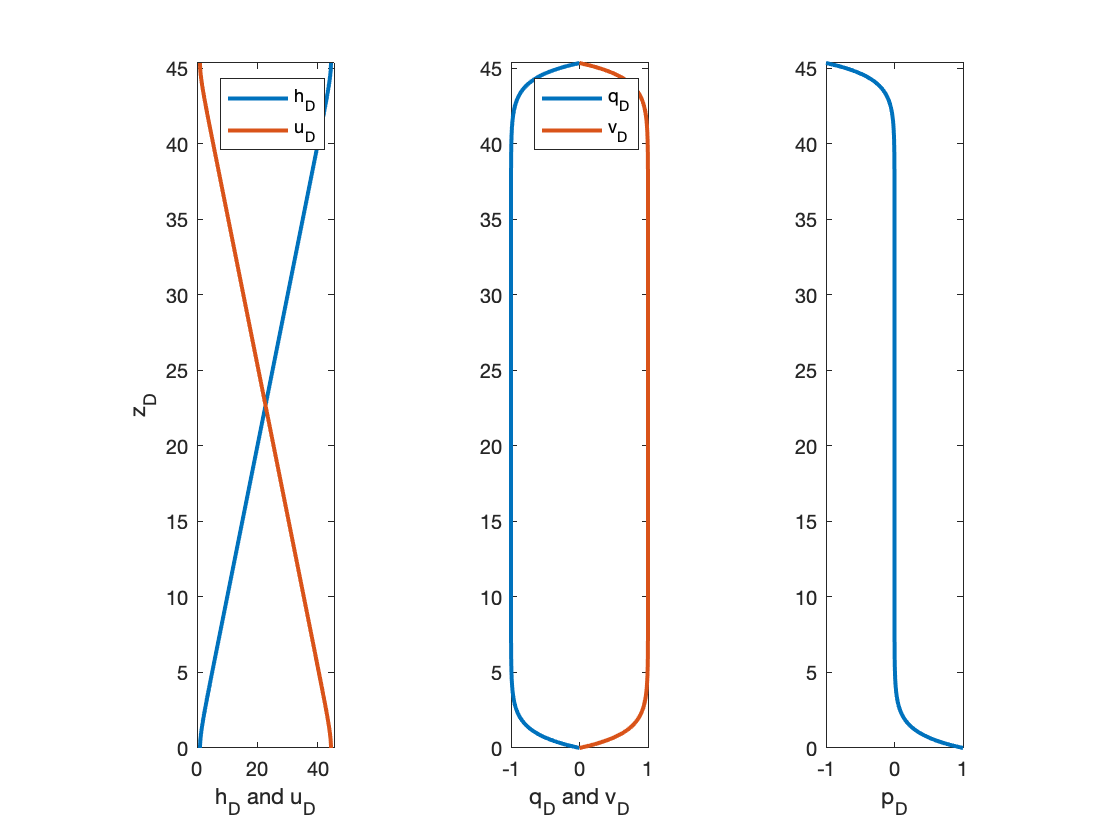

figure
clf
subplot 131
fplot(hSol(z),z,[0 Z],'linewidth',2), hold on
fplot(uSol(z),z,[0 Z],'linewidth',2)
pbaspect([.2,1,1])
xlim([0 Z])
xlabel 'h_D and u_D'
ylabel 'z_D'
legend('h_D','u_D')

subplot 132
fplot(q(z),z,[0 Z],'linewidth',2), hold on
fplot(v(z),z,[0 Z],'linewidth',2)
pbaspect([.2,1,1])
xlim([-1 1])
xlabel 'q_D and v_D'
legend('q_D','v_D')

subplot 133
fplot(p(z),z,[0 Z],'linewidth',2)
pbaspect([.2,1,1])
xlim([-1 1])
xlabel 'p_D'

## Plot Instantaneous Dimensional solution

syms hdim(zdim) udim(zdim) vsdim(zdim) vfdim(zdim) pdim(zdim) psolid(zdim) pfluid(zdim)
hdim(zdim) = hSol(1e3*zdim/sym(x_c))*sym(h_c)/1e3;
udim(zdim) = uSol(1e3*zdim/sym(x_c))*sym(u_c);
vsdim(zdim) = v(1e3*zdim/sym(x_c))*sym(v_c);
vfdim(zdim) = q((1e3*zdim/sym(x_c)))*sym(q_c)/phic;
pdim(zdim) = p((1e3*zdim/sym(x_c)))*sym(p_c);
psolid(zdim) = 1000*g*(H-zdim*1e3);
pfluid(zdim) = psolid(zdim) + pdim(zdim);

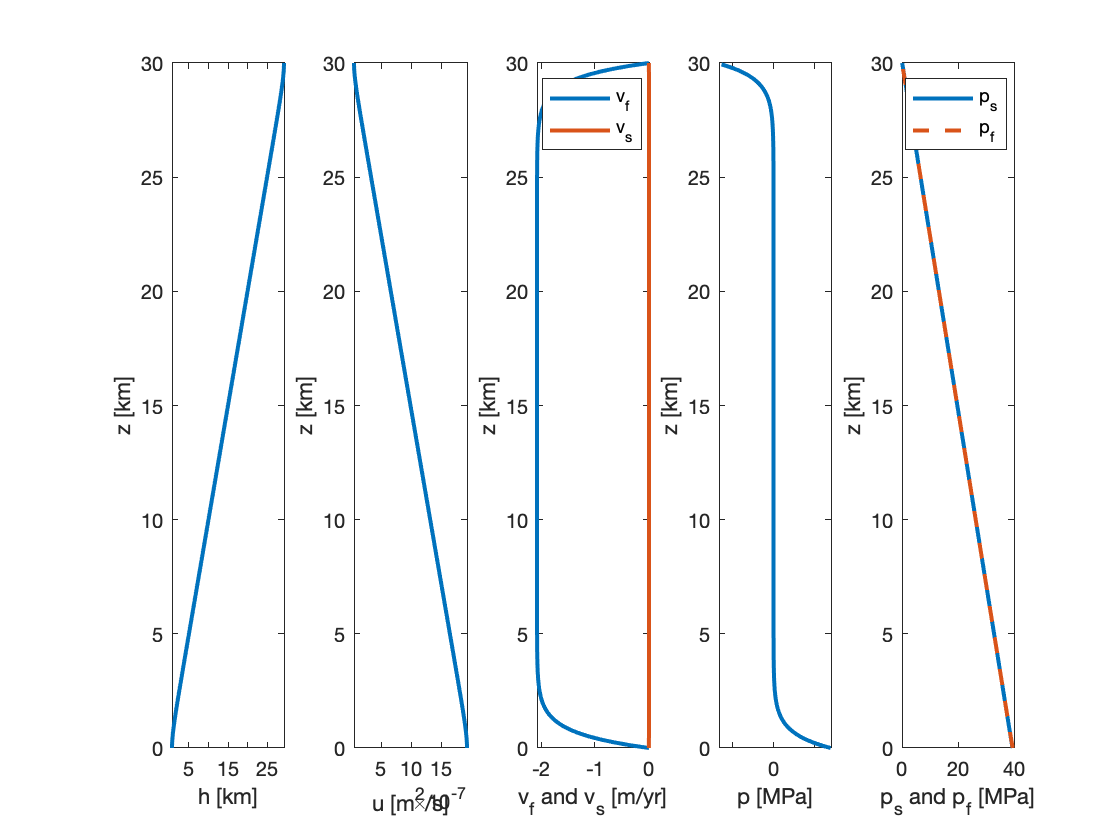


figure
clf
subplot 151
fplot(hdim(zdim),zdim,[0 H/1e3],'linewidth',2), hold on
xlabel 'h [km]'
ylabel 'z [km]'
subplot 152
fplot(udim(zdim),zdim,[0 H/1e3],'linewidth',2)
xlabel 'u [m^2/s]'
ylabel 'z [km]'
subplot 153
fplot(vfdim(zdim)*yr2sec,zdim,[0 H/1e3],'linewidth',2), hold on
fplot(vsdim(zdim)*yr2sec,zdim,[0 H/1e3],'linewidth',2)
xlabel 'v_f and v_s [m/yr]'
ylabel 'z [km]'
legend('v_f','v_s')
subplot 154
fplot(pdim(zdim)/1e6,zdim,[0 H/1e3],'linewidth',2)
xlabel 'p [MPa]'
ylabel 'z [km]'

subplot 155
fplot(psolid(zdim)/1e6,zdim,[0 H/1e3],'linewidth',2), hold on
fplot(pfluid(zdim)/1e6,zdim,[0 H/1e3],'linewidth',2,'LineStyle','--')
xlabel 'p_s and p_f [MPa]'
ylabel 'z [km]'
legend('p_s','p_f')